# Optimización en redes. Introducción

## Resumen.

En este live script se introducen los conceptos fundamentales de grafos, así como su representación matricial y gráfica.

## Representación matemática de Grafos. Matriz de Incidencia.

Se parte del grafo (no dirigido) G=(V,E), siendo V el conjunto de vértices o nodos, se supone V={1,2,..,n} y E el conjunto de aristas.

La matriz de incidencia es un matriz no cuadrada que tiene tantas filas como nodos y tantas columnas como aristas, asocia cada fila a un nodo y cada columna a una arista siendo todos los elementos de la matriz nulos excepto cuando incidan un nodo (i) y una arista (e), en cuyo caso el elemento $a_{i,e} =1$.

%  Sean V={1,2,..,4} y E={{1,2}; {1,4}; {2,3}; {2,4}; {3,4}}
%  La matriz de incidencia, suponiendo la ordenación de aristas anterior es la siguiente:
A=[1 1 0 0 0; 1 0 1 1 0; 0 0 1 0 1; 0 1 0 1 1]

A =      1     1     0     0     0
     1     0     1     1     0
     0     0     1     0     1
     0     1     0     1     1



% Para recuperar el número de nodos
n=size(A,1)

n = 4

% Para recuperar el número de aristas
m = size(A,2)

m = 5

## Representación matemática de Grafos. Matriz de Adyacencia.

La matriz de adyacencia es un matriz cuadrada con todos los elementos nulos excepto 1's en las celdas (i,j) asociadas a cada una de las aristas$\left\lbrace i,j\right\rbrace \in E\Leftrightarrow b_{i,j} =1$. 

Se puede representar sólo en la matriz triangular superior:

% Para el grafo anterior:
B=[0 1 0 1; 0 0 1 1; 0 0 0 1; 0 0 0 0]

B =      0     1     0     1
     0     0     1     1
     0     0     0     1
     0     0     0     0


n=size(B,1)

n = 4

m = sum(sum(B))

m = 5

 O se puede representar cada una de las aristas duplicadas, para obtener una matriz simétrica**.**

% Para el grafo anterior:
BB=[0 1 0 1; 1 0 1 1; 0 1 0 1; 1 1 1 0]

BB =      0     1     0     1
     1     0     1     1
     0     1     0     1
     1     1     1     0


n=size(BB,1)

n = 4

m=sum(sum(BB))/2

m = 5

## Representación matemática de Digrafos. Matriz de Incidencia.

Se parte del digrafo (grafo dirigido) G=(V,U), siendo V el conjunto de vértices o nodos, se supone V={1,2,..,n} y U el conjunto de arcos.

La matriz de incidencia es un matriz no cuadrada que tiene tantas filas como nodos y tantas columnas como arcos, asocia cada fila a un nodo y cada columna a un arco siendo todos los elementos de la matriz nulos excepto cuando incidan un nodo (i) y una arco (u=(i,j)), en cuyo caso el elemento $a_{i,u} =1$ y $a_{j,u} =-1$.

%  Sean V={1,2,..,4} y U={(1,2); (2,3); (2,4); (3,1); (3,4); (4,1)}
%  La matriz de incidencia, suponiendo la ordenación de aristas anterior es la siguiente:
A=[1 0 0 -1 0 -1; -1 1 1 0 0 0; 0 -1 0 1 1 0; 0 0 -1 0 -1 1]

A =      1     0     0    -1     0    -1
    -1     1     1     0     0     0
     0    -1     0     1     1     0
     0     0    -1     0    -1     1



% Para recuperar el número de nodos
n=size(A,1)

n = 4

% Para recuperar el número de aristas
m = size(A,2)

m = 6

## Representación matemática de Digrafos. Matriz de Incidencia.

La matriz de incidencia es un matriz cuadrada con todos los elementos nulos excepto 1's en las celdas $\left(i,j\right)$ asociadas a cada uno de los arcos $\left(i,j\right)\in U$.

En este caso, a diferencia del grafo, no hay que distinguir la matriz triangular superior o inferior.

% Para el digrafo anterior:
B=[0 1 0 0; 0 0 1 1; 1 0 0 1; 1 0 0 0]

B =      0     1     0     0
     0     0     1     1
     1     0     0     1
     1     0     0     0


n=size(B,1)

n = 4

m = sum(sum(B))

m = 6

## Representación por lista.

En algunas situaciones, los grafos (digrafos) se pueden representar a través de una lista de aristas (arcos) donde se especifican el extremo inicial y el extremo final.

% Para el grafo anterior
lista_grafo = [1 2 ; 1 4 ; 2 3 ; 2 4 ; 3 4]

lista_grafo =      1     2
     1     4
     2     3
     2     4
     3     4


% Para el digrafo anterior
lista_digrafo = [1 2 ; 2 3; 2 4; 3 1; 3 4 ; 4 1]

lista_digrafo =      1     2
     2     3
     2     4
     3     1
     3     4
     4     1


## Representación geométrica de grafos y digrafos.

La ventaja de los grafos es que permiten ilustrar visualmente los problemas, esto se logra representando los nodos en el plano y las aristas como segmentos uniendo los nodos extremos; en el caso de arcos, los segmentos se sustituyen por flechas que van desde el origen al extremo final.

% Para el grafo anterior, a partir de la representación por lista
lista_grafo_inicio = lista_grafo(:,1)

lista_grafo_inicio =      1
     1
     2
     2
     3


lista_grafo_final = lista_grafo(:,2)

lista_grafo_final =      2
     4
     3
     4
     4


% La representación por defecto es la siguiente
G=graph(lista_grafo_inicio,lista_grafo_final);
h=plot(G);

Por defecto, la representación gráfica toma unos determinados valores, que se pueden cambiar si se sabe cuál es la estructura de dicha representación:

h

h =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'}
     EdgeLabel: {}
         XData: [0.9803 0.4581 -0.9803 -0.4581]
         YData: [0.9803 -0.4581 -0.9803 0.4581]
         ZData: [0 0 0 0]

  Show all properties


Por ejemplo, para cambiar el color de los nodos o aristas:

h.NodeColor=[0 0 1 ]

h =   GraphPlot with properties:

     NodeColor: [0 0 1]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'}
     EdgeLabel: {}
         XData: [0.9803 0.4581 -0.9803 -0.4581]
         YData: [0.9803 -0.4581 -0.9803 0.4581]
         ZData: [0 0 0 0]

  Show all properties


h.EdgeColor=[0 1 0]

h =   GraphPlot with properties:

     NodeColor: [0 0 1]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 1 0]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'}
     EdgeLabel: {}
         XData: [0.9803 0.4581 -0.9803 -0.4581]
         YData: [0.9803 -0.4581 -0.9803 0.4581]
         ZData: [0 0 0 0]

  Show all properties


O para cambiar la localización de los nodos:

h.XData=[1 1 0 0.75]

h =   GraphPlot with properties:

     NodeColor: [0 0 1]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 1 0]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'}
     EdgeLabel: {}
         XData: [1 1 0 0.7500]
         YData: [0.9803 -0.4581 -0.9803 0.4581]
         ZData: [0 0 0 0]

  Show all properties


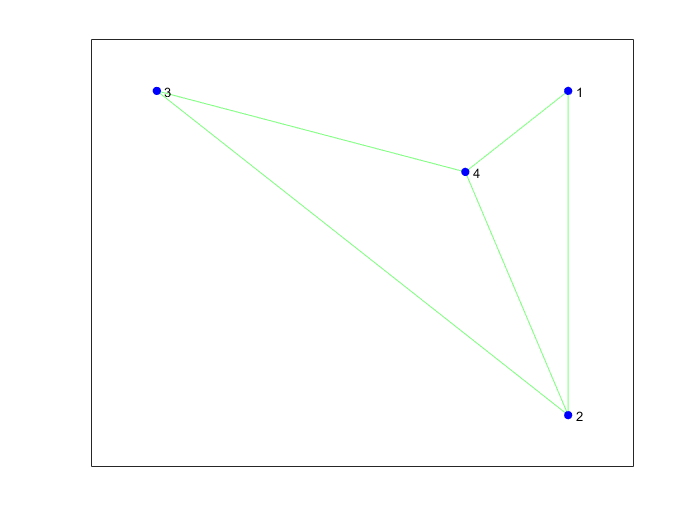

h =   GraphPlot with properties:

     NodeColor: [0 0 1]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 1 0]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'}
     EdgeLabel: {}
         XData: [1 1 0 0.7500]
         YData: [1 0 1 0.7500]
         ZData: [0 0 0 0]

  Show all properties


h.YData=[1 0 1 0.75]

Para el caso de digrafos, vale lo anterior, sustituyendo "graph" por "digraph"

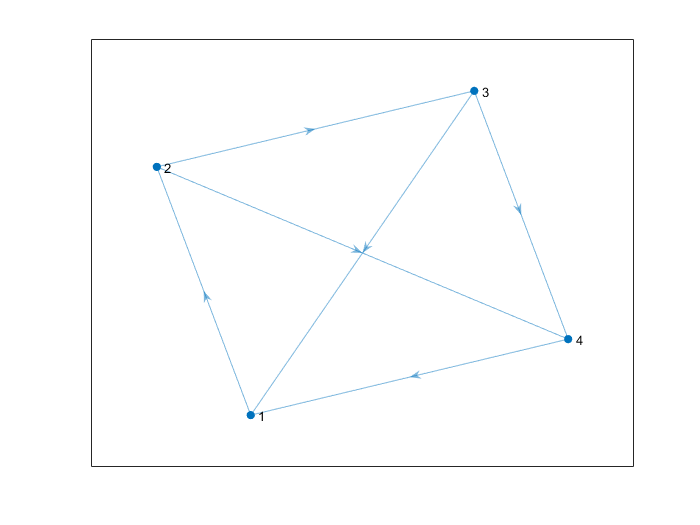

% Para el digrafo anterior, a partir de la representación por lista:
lista_digrafo_inicio = lista_digrafo(:,1);
lista_digrafo_final = lista_digrafo(:,2);
% La representación por defecto es la siguiente
D=digraph(lista_digrafo_inicio,lista_digrafo_final);
hd=plot(D);

lista_digrafo

lista_digrafo =      1     2
     2     3
     2     4
     3     1
     3     4
     4     1


Y la edición vale también para digrafos, por ejemplo, si se quiere modificar la representación del nodo 2:

% Cambiar las coordenadas del nodo 2 
% primero se visualizan las actuales
[hd.XData ; hd.YData]

ans =    -0.6560   -1.2078    0.6560    1.2078
   -1.2212    0.6488    1.2212   -0.6488


% luego se prueba hasta conseguir el efecto deseado (que no se corten las
% aristas)
hd.XData(2)=0.2;
hd.YData(2)=0.2;

O añadir etiquetas diferentes a los nodos o los arcos:

% Etiquetas de nodos:
hd.NodeLabel = {'a' 'b' 'c' 'd'}

hd =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'a'  'b'  'c'  'd'}
     EdgeLabel: {}
         XData: [-0.6560 0.2000 0.6560 1.2078]
         YData: [-1.2212 0.2000 1.2212 -0.6488]
         ZData: [0 0 0 0]

  Show all properties


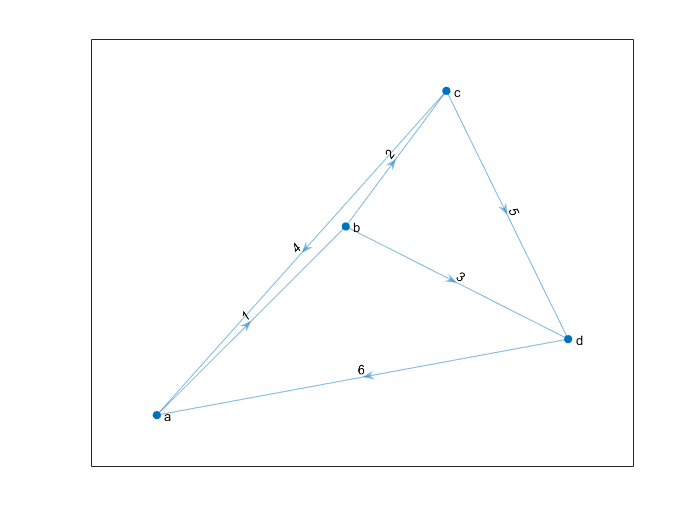

hd =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'a'  'b'  'c'  'd'}
     EdgeLabel: {'1'  '2'  '3'  '4'  '5'  '6'}
         XData: [-0.6560 0.2000 0.6560 1.2078]
         YData: [-1.2212 0.2000 1.2212 -0.6488]
         ZData: [0 0 0 0]

  Show all properties


% Etiquetas de aristas:
hd.EdgeLabel ={'1' '2' '3' '4' '5' '6'}